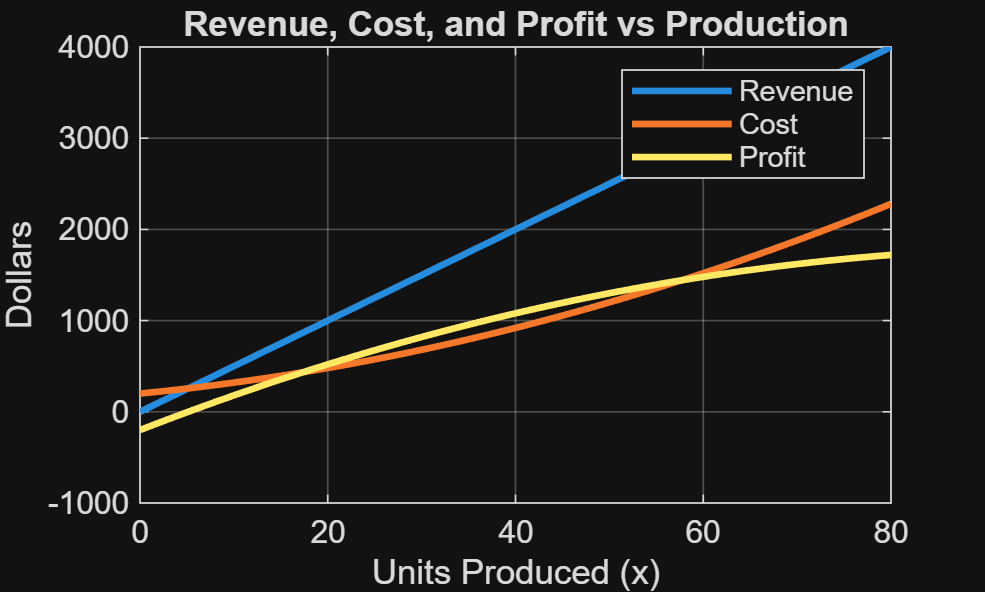

% Parameters
p = 50;
a = 0.2;
b = 10;
c = 200;

% Production levels
x = 0:1:80;

% Functions
R = p * x;
C = a * x.^2 + b * x + c;
P = R - C;

% Plot all three
figure;
plot(x, R, 'LineWidth', 2); hold on;
plot(x, C, 'LineWidth', 2);
plot(x, P, 'LineWidth', 2);
xlabel('Units Produced (x)');
ylabel('Dollars');
title('Revenue, Cost, and Profit vs Production');
legend('Revenue', 'Cost', 'Profit');
grid on;


% --- 4. Max Profit ---
[maxProfit, idx] = max(P);
x_maxProfit = x(idx);

fprintf('Maximum profit is %.2f at x = %d units.\n', maxProfit, x_maxProfit);

Maximum profit is 1720.00 at x = 80 units.



% --- 5. Break-even points ---
% Solve P(x) = 0 numerically
break_even_indices = find(abs(P) < 1); % tolerance ~1 dollar
x_break_even = x(break_even_indices);

fprintf('Approximate break-even points at x = ');

Approximate break-even points at x = 

fprintf('%d ', x_break_even);

fprintf('units.\n');

units.
